%Stability Region in (k_v,k_p) plane for the fixed value of k_i.(=0.5 in this case) 

clear all;close all;

syms kappa k_p k_v k_i d h v z c b v_star s omega;
A = [0 -1 0;k_p*kappa -b-2*v_star*c-k_p-k_v k_i ; kappa -1 0 ];
% where d = b+2*c*v
X = [h;v;z];
B = [1;k_v;0];
C = [0 1 0];
I = eye(3);

TF = C/(s*I-A)*B;
Char_Eqn = det(s*I-A);

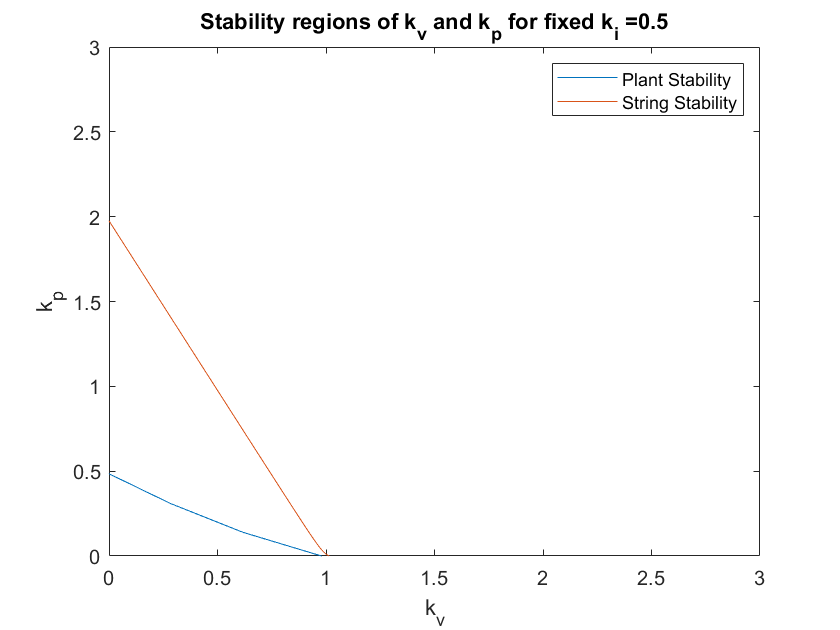

%Plant Stability
% s=i*om in characteristic equation,
% then plotting parametric equation in terms of omega.

subs(Char_Eqn,s,i*omega);

% Real Part = k_i*kappa - b*omega^2 - k_p*omega^2 - k_v*omega^2 -2*c*omega^2*v_star;
% Imagenery Part = k_i*omega - omega^3 + k_p*kappa*omega;

k_i = 0.5;
a = 0.1;
b = 0;
c = 0.0005;
v_max = 30;
h_go = 35;
h_stop = 5; 
v_star = 25;
kappa = v_max/(h_go-h_stop);
omega = 0:0.1:4*pi;

%In terms of parameter Omega.
k_p = (omega.^2-k_i)/kappa;
k_v = (k_i.*kappa -b.*omega.^2-k_p.*omega.^2-2.*c.*omega.^2.*v_star)./omega.^2;

figure(1); hold on; box on;
plot(k_v,k_p); %Plant Stability 
xlim([0 3]);
ylim([0 3]);


%String Stability
% s=i*om in transferfunction,
% then taking it's magnitude as less than zero.

syms kappa k_p k_v k_i d h v z c b v_star s omega;

TF_iomega = subs(TF,s,i*omega);
num = (-k_i*kappa-k_p*kappa*omega*1i+k_v*omega^2);
deno = b*omega^2 - k_i*omega*1i - k_i*kappa + k_p*omega^2 +...
       k_v*omega^2 + omega^3*1i + 2*c*omega^2*v_star - k_p*kappa*omega*1i;

real_num = -k_i*kappa + k_v*omega^2;
img_num = -k_p*kappa*omega;
real_deno = b*omega^2 - k_i*kappa +k_v*omega^2+ k_p*omega^2 + 2*c*omega^2*v_star;
img_deno = -k_i*omega + omega^3 - k_p*kappa*omega;

P = ((real_num^2 + img_num^2 - real_deno^2 - img_deno^2)/omega^2);
eqn = diff(P,omega)==0;
omega_critical = solve(eqn,omega);
omega_cr = omega_critical(2);
cond_eqn = subs(P,omega,omega_cr) == 0;
k_p = solve(cond_eqn,k_p);
k_p(1);


k_i = 0.5;
a = 0.1;
b = 0;
c = 0.0005;
v_max = 30;
h_go = 35;
h_stop = 5; 
v_star = 25;
kappa = v_max/(h_go-h_stop);
omega = 0:0.1:2*pi;

k_v = 0:0.01:3;
k_p = kappa - k_v - b - 2.*c.*v_star +...
     (2.*k_i - 2.*b.*kappa - 2*(k_i.^2 - 2.*b.*k_i.*kappa -...
     4.*c.*k_i.*kappa.*v_star).^(1/2) - 2.*k_v.*kappa + k_v.^2 +...
     kappa^2 - 4*c*kappa*v_star).^(1/2);

 
plot(k_v,k_p); %String Stability
xlabel("k_v");
ylabel("k_p");
title(['Stability regions of k_v and k_p for fixed k_i =', num2str(k_i)]);
legend("Plant Stability","String Stability");

saveas(gcf,"Output_Graphs\PIV_Controller_for_Adaptive_Cruise_Control_Stability_Regions\Stability_Regions.jpg");



%%Reference HW3 Q4 ME542